# HW04 - Scuderi -1937090

clear all 
s = tf('s');
t = 0:0.01:10;
om = logspace(-2,2,600);

# Problem 1: Robust Performance

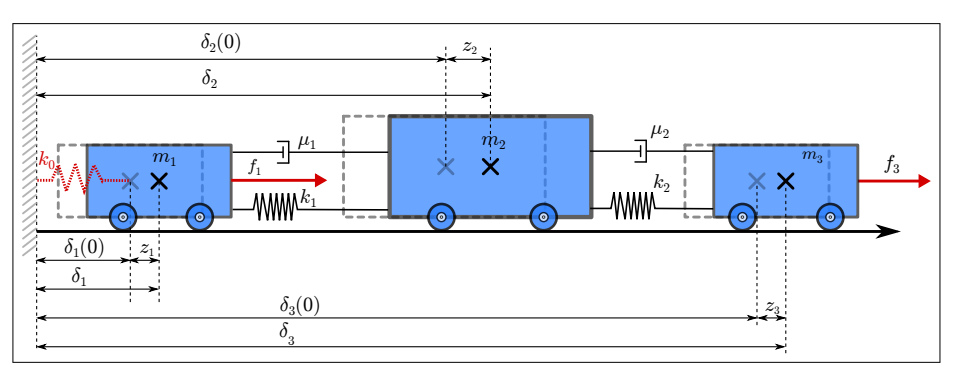

To consider the same condition on the homweork 3 I load the same workspace into the current one .

% Nominal Parameters
m1 =1; 
m2 =1.5;
m3 =0.5;
k0 =5;
k1 =10;
k2 =100;
mu1 = 5;
mu2 = 15;
d1 = 0.1; 
d2 = 0.2; 
d3 = 0.1;

% Uncertain Parameters
m1_unc = ureal('m1',m1,'Percentage',10,'AutoSimplify','full');
m2_unc = ureal('m2',m2,'Percentage',10,'AutoSimplify','full');
m3_unc = ureal('m3',m3,'Percentage',10,'AutoSimplify','full');

A11 = zeros(3,3);
A12 = eye(3);
A21_unc = [-(k0+k1)/m1_unc k1/m1_unc 0;
        k1/m2_unc -(k1+k2)/m2_unc k2/m2_unc;
        0 k2/m3_unc -k2/m3_unc];
A22_unc = [-(mu1+d1)/m1_unc mu1/m1_unc 0;
        mu1/m2_unc -(mu1+mu2+d2)/m2_unc mu2/m2_unc
        0 mu2/m3_unc -(mu2+d3)/m3_unc];
A_unc = [A11, A12;
    A21_unc, A22_unc];
B_unc = [zeros(3,2); 1/m1_unc 0; 0 0; 0 1/m3_unc];

C = [[1 0 0; 0 0 1], zeros(2,3)];

D = zeros(2,2);

% Uncertain State Space Representation
MSD_unc = ss(A_unc,B_unc,C,D);

MSD_unc.StateName = {'m1 displacement (m)';'m2 displacement (m)';'m3 displacement (m)';...
                  'm1 velocity (m/s)';'m2 velocity (m/s)';'m3 velocity (m/s)'};
MSD_unc.y  = 'y';
MSD_unc.u = 'u_bar';

## Simulation Augmented Plant

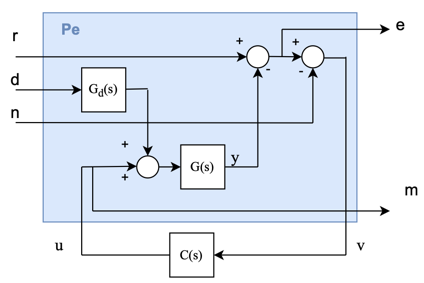

G = tf(MSD_unc.Nominal)

G =
 
  From input "u_bar(1)" to output...
                      s^4 + 43.67 s^3 + 380 s^2 + 908 s + 1333
   y(1):  -----------------------------------------------------------------
          s^6 + 48.77 s^5 + 601.1 s^4 + 2931 s^3 + 6251 s^2 + 5073 s + 6667
 
                              100 s^2 + 866.7 s + 1333
   y(2):  -----------------------------------------------------------------
          s^6 + 48.77 s^5 + 601.1 s^4 + 2931 s^3 + 6251 s^2 + 5073 s + 6667
 
  From input "u_bar(2)" to output...
                              100 s^2 + 866.7 s + 1333
   y(1):  -----------------------------------------------------------------
          s^6 + 48.77 s^5 + 601.1 s^4 + 2931 s^3 + 6251 s^2 + 5073 s + 6667
 
                    2 s^4 + 37.13 s^3 + 280.7 s^2 + 1019 s + 2067
   y(2):  -----------------------------------------------------------------
          s^6 + 48.77 s^5 + 601.1 s^4 + 2931 s^3 + 6251 s^2 + 5073 s + 6667
 
Continuous-time transfer function.


G.u = 'u_bar'; G.y = 'y';

Gd = tf([0.1; 0]); Gd.u = 'd'; Gd.y = 'd_bar';

Sum1 = sumblk('ey = r - y',2);
Sum2 = sumblk('v = ey - n',2);
Sum3 = sumblk('u_bar = u + d_bar',2);

Pe = minreal(connect(G, Gd, Sum1,Sum2,Sum3, {'r','d','n','u'},{'ey','u','v'}));

6 states removed.


Pe_sim = minreal(connect(MSD_unc, Gd, Sum1,Sum2,Sum3, {'r','d','n','u'},{'ey','u','v'}));

## Synthesys Augmented Plant

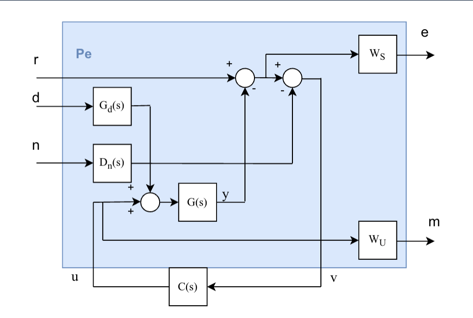

% Sensitivity Weight
Ms = 1.01;
B3s = 0.8;
As = 0.01;

Ws = (s/Ms+B3s)/(s+B3s*As);

% Control Sensitivity Weight
wS = Ws*eye(2); wS.u = 'ey'; wS.y = 'ey_sens';

% Control Sensitivity Weight
wU = tf(0.01*eye(2)); wU.u = 'u'; wU.y = 'u_sens';

% Noise Weight Scaling Matrix
Dn = tf(0.1*eye(2)); Dn.u ='n_bar'; Dn.y = 'n';

% Augmented Plant for Controller Synthesis (uncertain augmented)
Pe_unc = minreal(connect(MSD_unc, Gd, Sum1,Sum2,Sum3, wS, wU,Dn, {'r','d','n_bar','u'},{'ey_sens','u_sens','v'}));

% "Pull out" uncertainty 
[Pe_cert,delta,BlkStruct] = lftdata(Pe_unc);
Pe_cert = minreal(Pe_cert);

## Load controllers into workspace (Same as HW03)

% Designed on Pe_syn with hinfsyn
C_hinfsyn = load('C1_hinf.mat').C1;

% Designed on G (nominal plant) with mixsyn
C_mixsyn = load('C2_hinf.mat').C2;

% Designed on Pe_unc (uncertain augmented) with musyn
C_musyn = load('C_musyn.mat').C_mu;

% Close Controller loopo (lower LFT)
Cl_cert1 = lft(Pe_cert, C_hinfsyn);
Cl_cert2 = lft(Pe_cert, C_mixsyn);
Cl_cert3 = lft(Pe_cert, C_musyn);

% Uncertainty block with the following structure
% 3x3 real diagonal uncertainty (same as Delta) [size(N11)]
% 5x4 full-complex block ("fake Uncertainty") [size(N22)]
blockdiag = [-3 0; 5 4];

## Robust Performance

% SSV for hinfsyn
ssv_bounds1 = mussv(frd(Cl_cert1,om),blockdiag);

Points completed: 600/600


% SSV for mixsyn
ssv_bounds2 = mussv(frd(Cl_cert2,om),blockdiag);

Points completed: 600/600


% SSV for musyn
ssv_bounds3 = mussv(frd(Cl_cert3,om),blockdiag);

Points completed: 600/600


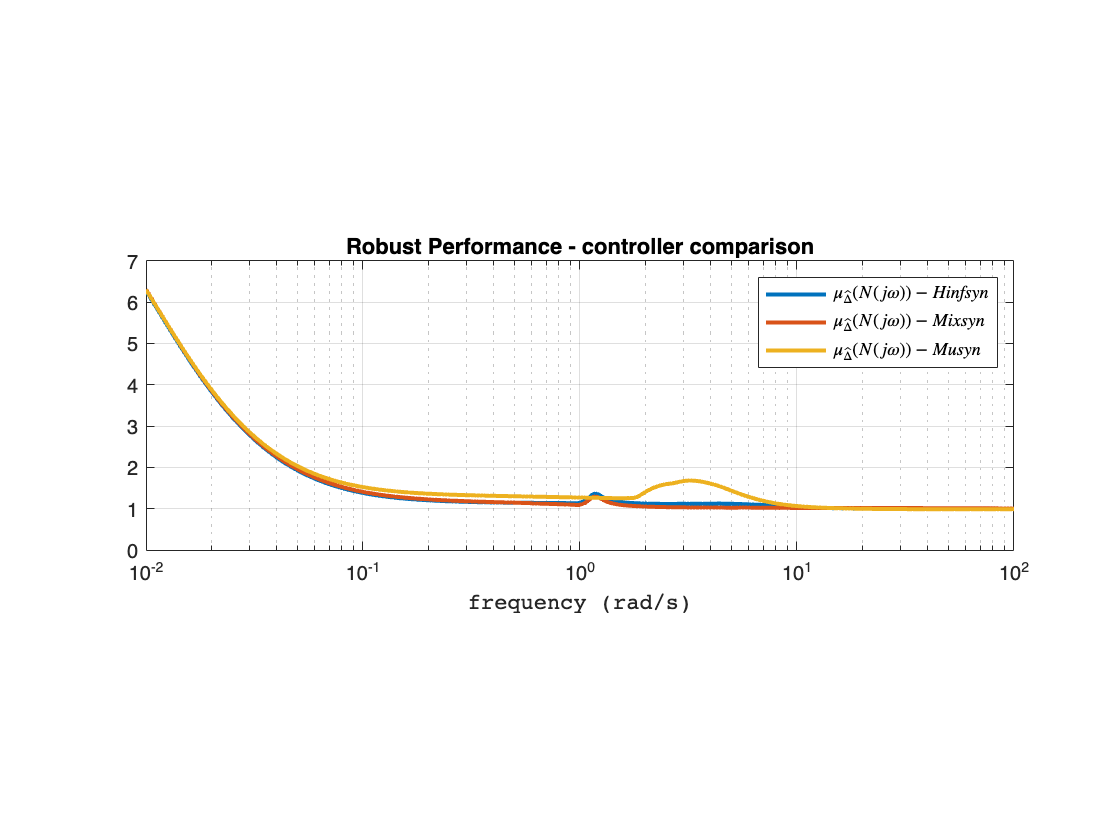

% Bode Magnitude for SSVs
[mag1,~] = bode(ssv_bounds1(1,1),om);
[mag2,~] = bode(ssv_bounds2(1,1),om);
[mag3,~] = bode(ssv_bounds3(1,1),om);

% Plot Mu_^Delta(N) for all controllers 
figure()
semilogx(om,mag1(:),om,mag2(:),om,mag3(:),'LineWidth',2), grid
legend('$\mu_{\hat \Delta} (N(j\omega)) - Hinfsyn$','$\mu_{\hat \Delta} (N(j\omega)) - Mixsyn$', ...
    '$\mu_{\hat \Delta} (N(j\omega)) - Musyn$','Interpreter','latex')
xlabel('frequency (rad/s)','FontName','Courier');
title('Robust Performance - controller comparison')
pbaspect([3 1 1])

## New Robust Controller Design

% New Noise Weight Scaling Matrix
Dn2 = tf(0.01*eye(2)); Dn2.u = 'n_bar'; Dn2.y = 'n';

% New Control Sensitivity Weight
wU2 = tf([1/500 0; 0 1/500]); wU2.u = 'u'; wU2.y = 'u_sens';

% New Sensitivity Weight
Ms2 = 1.03;
B3s2 = 0.5;
As2 = 0.03;

Ws2 = (s/Ms2+B3s2)/(s+B3s2*As2);

wS_mu = [Ws2 0; 0 Ws2];
wS_mu.u = 'ey'; wS_mu.y = 'ey_sens';

% New uncertain augmented plant with the new weights
Pe_mu = minreal(connect(MSD_unc, Gd, Sum1,Sum2,Sum3, wS_mu, wU2,Dn2, {'r','d','n_bar','u'},{'ey_sens','u_sens','v'}));

% New "certain" plant with the new weights
[Pe_mu_cert,~,~] = lftdata(Pe_mu);

% Mu-synthesis of new controller
[C_mu,rp_mu] = musyn(Pe_mu,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           1.271        1.231        1.244            14
    2           1.056        1.049        1.061            14
    3           1.024        1.015        1.026            14
    4           1.012        1.003        1.014            20
    5           1.007       0.9992        1.008            18
    6           1.007       0.9986        1.008            26

Best achieved robust performance: 0.999



The robust performance index is below one, let's check again with the $\mu_{\hat{\Delta}}(N)$ plot.

Cl_mu_cert1 = lft(Pe_mu_cert, C_hinfsyn);
Cl_mu_cert2 = lft(Pe_mu_cert, C_mixsyn);
Cl_mu_cert3 = lft(Pe_mu_cert, C_musyn);
Cl_mu_cert4 = lft(Pe_mu_cert, C_mu);

% SSV for hinfsyn
ssv_mu_bounds1 = mussv(frd(Cl_mu_cert1,om),blockdiag);

Points completed: 600/600


% SSV for mixsyn
ssv_mu_bounds2 = mussv(frd(Cl_mu_cert2,om),blockdiag);

Points completed: 600/600


% SSV for musyn
ssv_mu_bounds3 = mussv(frd(Cl_mu_cert3,om),blockdiag);

Points completed: 600/600


% SSV for new musyn
ssv_mu_bounds4 = mussv(frd(Cl_mu_cert4,om),blockdiag);

Points completed: 600/600


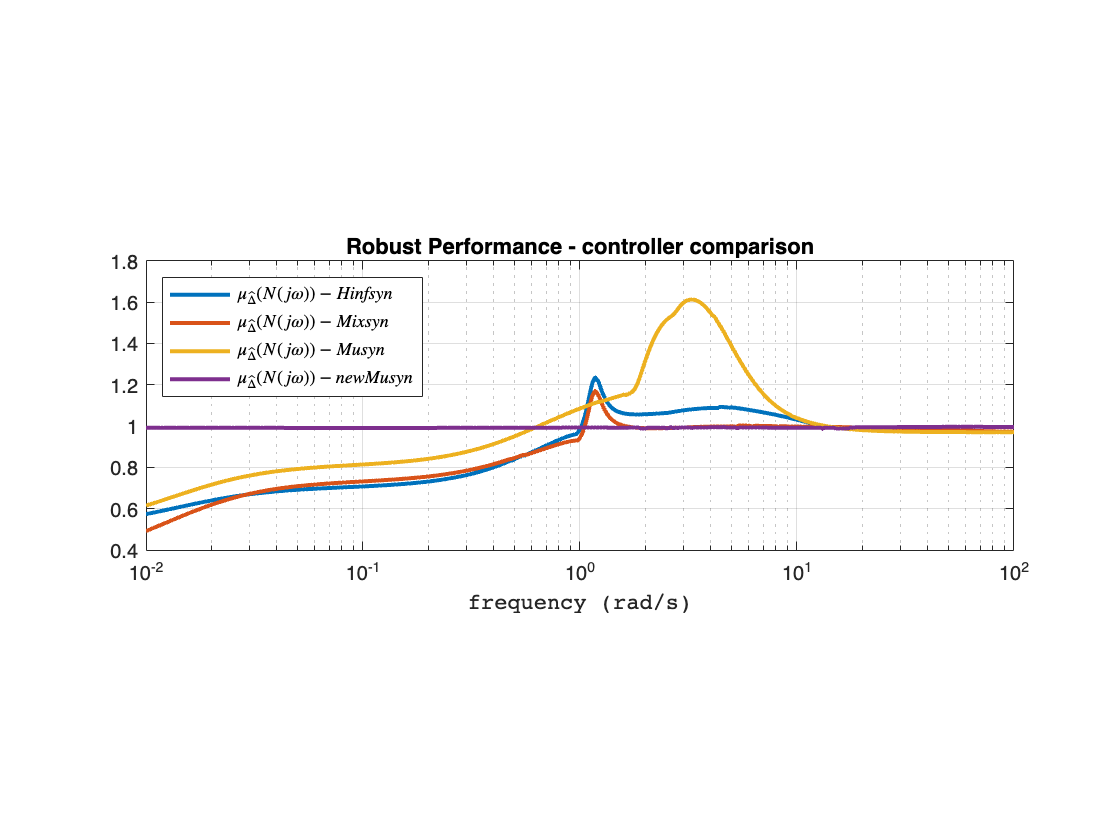

% Bode Magnitude for SSVs
[mag1,~] = bode(ssv_mu_bounds1(1,1),om);
[mag2,~] = bode(ssv_mu_bounds2(1,1),om);
[mag3,~] = bode(ssv_mu_bounds3(1,1),om);
[mag4,~] = bode(ssv_mu_bounds4(1,1),om);

% Plot Mu_^Delta(N) for all controllers 
figure()
semilogx(om,mag1(:),om,mag2(:),om,mag3(:),om,mag4(:),'LineWidth',2), grid
legend('$\mu_{\hat \Delta} (N(j\omega)) - Hinfsyn$','$\mu_{\hat \Delta} (N(j\omega)) - Mixsyn$', ...
    '$\mu_{\hat \Delta} (N(j\omega)) - Musyn$', ...
    '$\mu_{\hat \Delta} (N(j\omega)) - new Musyn$','Location','Northwest','Interpreter','latex')
xlabel('frequency (rad/s)','FontName','Courier');
title('Robust Performance - controller comparison')
pbaspect([3 1 1])

## Simulation Plots

% Sample Uncertain Simulation Plant
n_samp = 40;
Pe_samp = usample(Pe_sim,n_samp);

% Sampled Closed loops: 
Cl_sim_unc1 = lft(Pe_samp, C_mu);
Cl_sim_unc2 = lft(Pe_samp, C_hinfsyn);

% Position reference [r1 r3]
r = [0.5; 1.5];

% Disturbance on first mass (scaled)
d = 1;

% Generate random noise
noise = ones(2,length(t));
for i=1:length(t)
    noise(:,i) = 0.01*rand(2,1);
end

% Input vector for augmented plant
input = [ones(2,length(t)).*r;
        ones(1,length(t))*d;
        noise];

y1 = zeros(length(t),4,n_samp);
y2 = y1;
% Augmented plant output with Hinfsyn Controller
for i=1:n_samp
[y1(:,:,i), t1] = lsim(Cl_sim_unc1(:,:,i), input, t);

% Augmented plant output with Mixsyn Controller
[y2(:,:,i), t2] = lsim(Cl_sim_unc2(:,:,i), input, t);
end



#### Response Plot

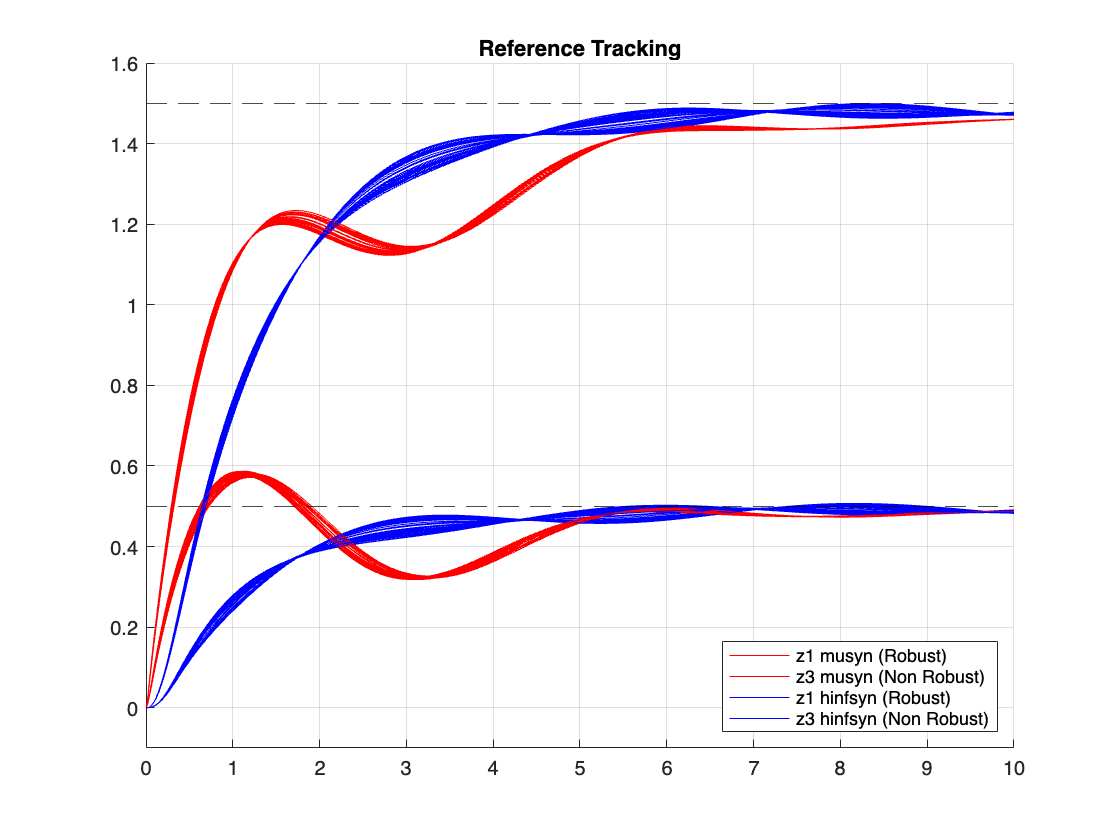

figure()
hold on
grid on
for i=1:n_samp
    plot(t1, -(y1(:,1,i)-r(1)),'r',t1, -(y1(:,2,i)-r(2)),'r',t2, -(y2(:,1,i)-r(1)),'b',t2, -(y2(:,2,i)-r(2)),'b','LineWidth',0.5)
end

yline(r(1),'k--');
yline(r(2),'k--');
ylim([-0.1,1.6])
title("Reference Tracking")
legend("z1 musyn (Robust)",'z3 musyn (Non Robust)',"z1 hinfsyn (Robust)",'z3 hinfsyn (Non Robust)','Location','southeast')

#### Control Effort Plot

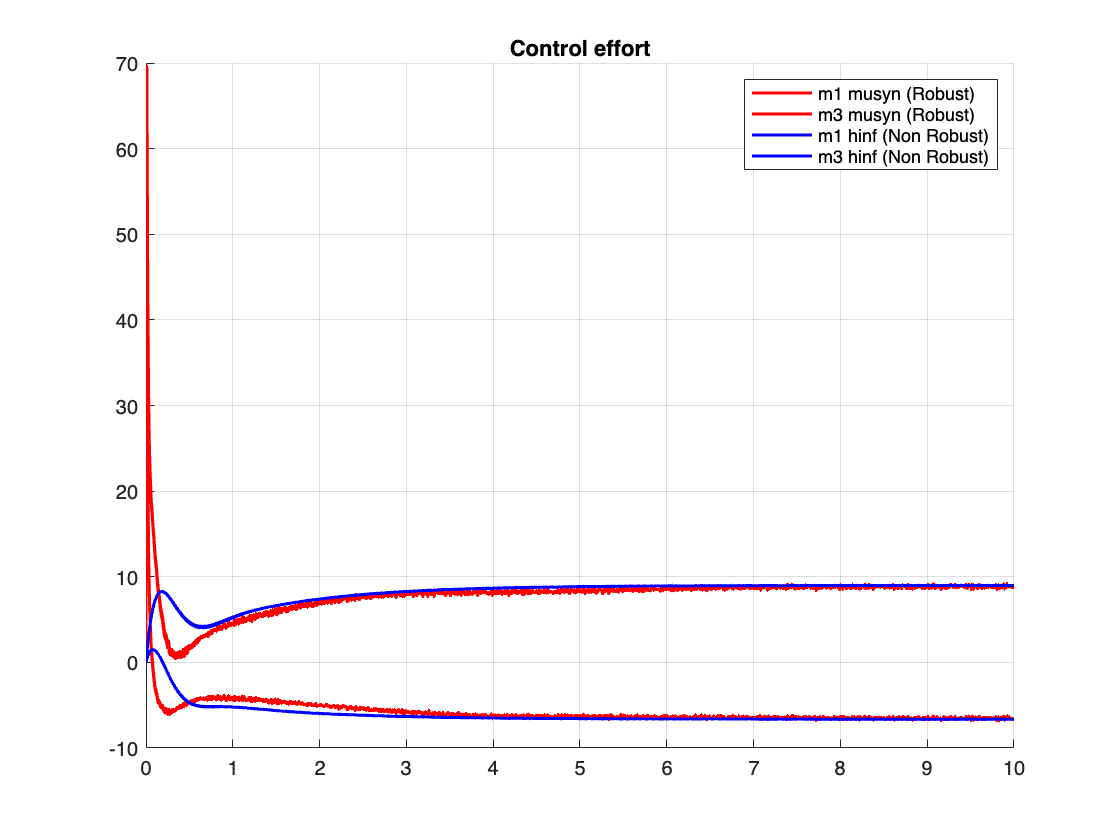

figure()
hold on
grid on
for i=1:n_samp
plot(t1, y1(:,3,i),'r',t1, y1(:,4,i),'r',t2, y2(:,3,i),'b',t2, y2(:,4,i),'b','LineWidth',1.5)
end
title("Control effort")
legend("m1 musyn (Robust)",'m3 musyn (Robust)',"m1 hinf (Non Robust)",'m3 hinf (Non Robust)')

# Problem 2: MIMO Zeroes

### TITO SYSTEM

% Nominal Parameters
m1 =1; 
m2 =1.5;
m3 =0.5;
k0 =5;
k1 =10;
k2 =100;
mu1 = 5;
mu2 = 15;
d1 = 0.1; 
d2 = 0.2; 
d3 = 0.1;

A11 = zeros(3,3);
A12 = eye(3);
A21 = [-(k0+k1)/m1 k1/m1 0;
        k1/m2 -(k1+k2)/m2 k2/m2;
        0 k2/m3 -k2/m3];
A22 = [-(mu1+d1)/m1 mu1/m1 0;
        mu1/m2 -(mu1+mu2+d2)/m2 mu2/m2
        0 mu2/m3 -(mu2+d3)/m3];

A = [A11, A12;
    A21, A22];
B = [zeros(3,2); 1/m1 0; 0 1/m2; 0 0];

C = [[1 0 0; 0 1 0], zeros(2,3)];

D = zeros(2,2);

% TITO State Space Representation
MSD = minreal(ss(A,B,C,D)); MSD.u = {'f1','f2'}; MSD.y = {'z1','z2'};

% Visualize TITO Transfer Function Matrix 
G_zpk = zpk(MSD)

G_zpk =
 
  From input "f1" to output...
                   (s+32.92) (s+8.109) (s^2 + 2.633s + 4.994)
   z1:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
                        3.3333 (s+20.39) (s+9.808) (s+2)
   z2:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
  From input "f2" to output...
                        3.3333 (s+20.39) (s+9.808) (s+2)
   z1:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
                  0.66667 (s+20.39) (s+9.808) (s^2 + 5.1s + 15)
   z2:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
Continuous-time zero/pole/gain model.


% Matlab transmission zeros command
t_zeros = tzero(MSD)

t_zeros =    -9.8076
  -20.3924


% All g_ij share the same denominator
polez = pole(MSD)

polez =  -33.1247 + 0.0000i
  -7.7496 + 0.0000i
  -3.8146 + 1.9462i
  -3.8146 - 1.9462i
  -0.1315 + 1.1827i
  -0.1315 - 1.1827i


## Explicit Calculation

% Use x a symbolic variable instead of s
syms x

% Extract Numerators and deominator Coefficients   
[n11,d] = tfdata(MSD(1,1));
[n12,~] = tfdata(MSD(1,2));
[n21,~] = tfdata(MSD(2,1));
[n22,~] = tfdata(MSD(2,2));

% Symbolic matrix G with "x" instead of "s" 
d = poly2sym(d,x);
G_sym = [poly2sym(n11,x),poly2sym(n12,x); 
    poly2sym(n21,x) poly2sym(n22,x)]/d;

% Calculate determinant of G
detG = det(G_sym);

% Find candidates for trasmission zeros solving det|G| = 0
candidates = double(solve(detG == 0, x));
tzeros = [];

% Check if the candidate is not a pole
for i=1:length(candidates)
    z = candidates(i);
    discard = 0;
    for j=1:length(polez)
        if norm(z - polez(j)) < 1e-8
            discard = 1;
            break
        end
    end
    % Add to the transmission zeros list if not a pole
    if ~discard
       tzeros = [tzeros; candidates(i)];
    end
end

% Transmission zeros
tzeros

tzeros =   -20.3924
   -9.8076


#### Equivalently, with rosembrock formulation

I = eye(size(A));
S = [x*I-A -B; C D];

% Obtain the transmissions zeros again as det|S| = 0
double(solve(det(S) == 0,x))

ans =   -20.3924
   -9.8076


% Equivalently
eq = simplify(det(G_sym)/det(x*I -A));
double(solve(eq == 0,x))

ans =   -20.3924
   -9.8076


% Rosenbrock System Matrix
S = [s*I-A -B; C D];

#### First zero

z1 = t_zeros(1);

S1 = evalfr(S,z1);

% Generalized Input Direction for first zero 
% Rescale to make quantities larger 
% (show that the zero is actually blocking and not just because of small quantities)
i1 = 10*null(S1) 

i1 =    -0.0000
    0.0000
    0.2078
    0.0000
   -0.0000
   -2.0376
    0.0000
    9.7880


% First Zero State vector
x01 = i1(1 : length(A));
% First Zero Input vector
u01 = i1(length(A)+1 : end);

z2 = t_zeros(2);
S2 = evalfr(S,z2);

% Generalized Input Direction for second zero
% Rescale to make quantities larger 
% (show that the zero is actually blocking and not just because of small quantities
i2 = null(S2)

i2 =     0.0000
    0.0000
    0.0048
   -0.0000
   -0.0000
   -0.0986
    0.0000
    0.9951


% Zero State vector
x02 = i2(1 : length(A));
% Zero Input direction vector
u02 = i2(length(A)+1 : end);

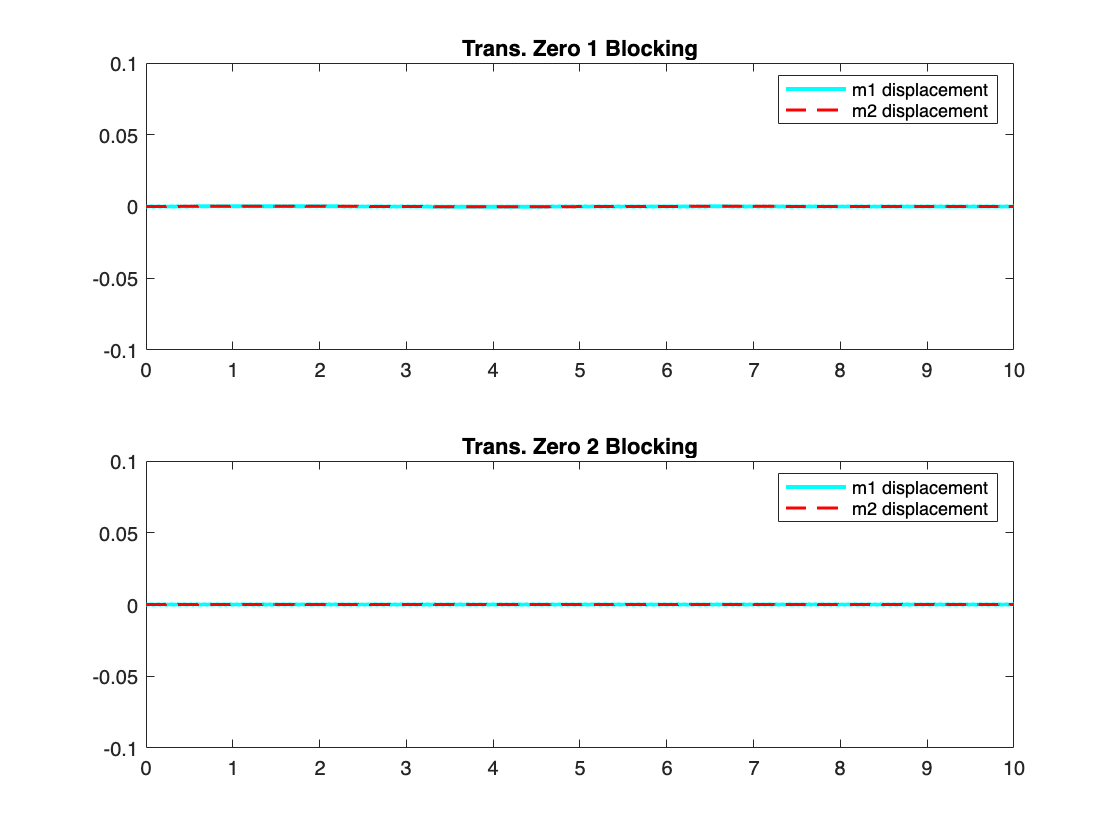

% Simulation Time
t = 0:0.01:10;

% First zero blocking input 
u1 = u01*exp(z1*t);

% Second zero blocking input
u2 = u02*exp(z2*t);

% Simulation 
[y1,t1] = lsim(MSD,u1,t,x01);
[y2,t2] = lsim(MSD,u2,t,x02);

figure()
subplot(2,1,1)
plot(t1,y1(:,1),'c','LineWidth',2)
hold on
plot(t1,y1(:,2),'r--', 'LineWidth',1.5)
ylim([-0.1,0.1])
title("Trans. Zero 1 Blocking")
legend('m1 displacement', 'm2 displacement')

subplot(2,1,2)
plot(t2,y2(:,1),'c','LineWidth',2)
hold on
plot(t2,y2(:,2),'r--', 'LineWidth',1.5)
ylim([-0.1,0.1])
title("Trans. Zero 2 Blocking")
legend('m1 displacement', 'm2 displacement')

o1 = null(S1'); 
o1 = o1';

o2 = null(S2');
o2 = o2';

## TISO System

B_tiso = [zeros(3,2); 1/m1 0; 0 1/m2; 0 0];
C_tiso = [0 1 0 zeros(1,3)];
D_tiso = zeros(1,2);

% TISO State Space Representation
MSD_TISO = minreal(ss(A,B_tiso,C_tiso,D_tiso)); 
MSD_TISO.u = {'f1','f2'}; MSD_TISO.y = {'z2'};

% Visualize TITO Transfer Function Matrix 
TISO_zpk = zpk(MSD_TISO)

TISO_zpk =
 
  From input "f1" to output "z2":
                  3.3333 (s+20.39) (s+9.808) (s+2)
  -----------------------------------------------------------------
  (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
  From input "f2" to output "z2":
            0.66667 (s+20.39) (s+9.808) (s^2 + 5.1s + 15)
  -----------------------------------------------------------------
  (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
Continuous-time zero/pole/gain model.


tz_tiso = tzero(MSD_TISO)

tz_tiso =   -20.3924
   -9.8076


% Use rank loss method
Sx = [x*I-A -B_tiso; C_tiso D_tiso];
double(solve(simplify(det(Sx*Sx')) == 0,x))

ans =   -20.3924
  -20.3924
   -9.8076
   -9.8076


% Rosenbrock System Matrix
S_TISO = [s*I-A -B_tiso; C_tiso D_tiso];

#### First Zero

z1_tiso = tz_tiso(1);

S1_tiso = evalfr(S_TISO,z1_tiso);

% Dimension 2 nullspace -> any linear combination works
% as a valid inout direction
i1_tiso = null(S1_tiso);

% Chosen generalized input dimension
i1_tiso = 2*i1_tiso(:,1)+8*i1_tiso(:,2);  

% First Zero State vector
x01_tiso = i1_tiso(1 : length(A));

% First Zero Input vector
u01_tiso = i1_tiso(length(A)+1 : end);

% First zero blocking input 
u1_tiso = u01_tiso*exp(z1_tiso*t);

#### Second Zero

% Second Transmission zero
z2_tiso = tz_tiso(2);

S2_tiso = evalfr(S_TISO,z2_tiso);

% Dimension 2 nullspace -> any linear combination works
% as a valid inout direction
i2_tiso = null(S2_tiso);

% Chosen generalized input dimension
i2_tiso = 6*i2_tiso(:,1)+4*i2_tiso(:,2);  

% First Zero State vector
x02_tiso = i2_tiso(1 : length(A));

% First Zero Input vector
u02_tiso = i2_tiso(length(A)+1 : end);

% First zero blocking input 
u2_tiso = u02_tiso*exp(z2_tiso*t);

#### Simulation

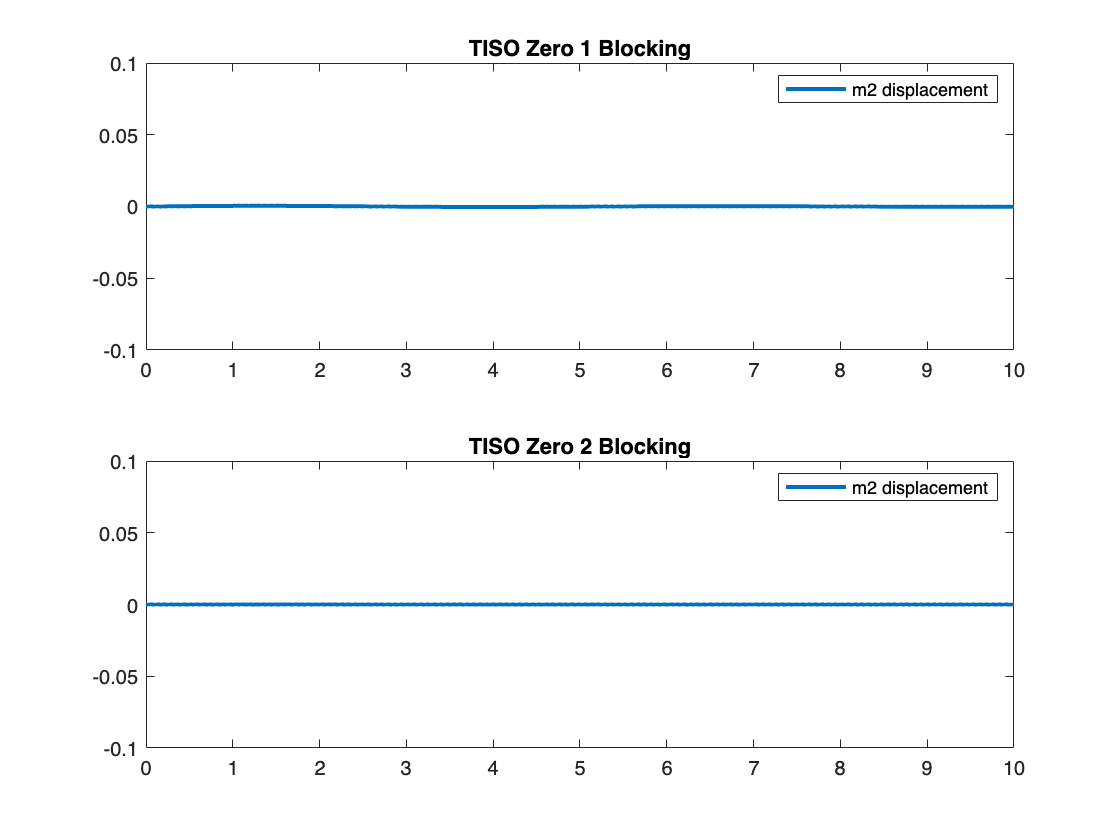

% Simulation 
[y1_tiso,t1_tiso] = lsim(MSD_TISO,u1_tiso,t,x01_tiso);
[y2_tiso,t2_tiso] = lsim(MSD_TISO,u2_tiso,t,x02_tiso);

figure()
subplot(2,1,1)
plot(t1_tiso,y1_tiso(:,1),'LineWidth',2)
ylim([-0.1,0.1])
title("TISO Zero 1 Blocking")
legend('m2 displacement')
subplot(2,1,2)
plot(t2_tiso,y2_tiso(:,1),'LineWidth',2)
ylim([-0.1,0.1])
title("TISO Zero 2 Blocking")
legend('m2 displacement')

## SITO System

B_sito = [zeros(3,1); 1/m1; 0; 0];
C_sito = [[0 1 0; 0 0 1], zeros(2,3)];
D_sito = zeros(2,1);

% SITO State Space Representation
MSD_SITO = minreal(ss(A,B_sito,C_sito,D_sito)); 
MSD_SITO.u = {'f1'}; MSD_SITO.y = {'z2','z3'};

% Visualize SITO Transfer Function Matrix 
SITO_zpk = zpk(MSD_SITO)

SITO_zpk =
 
  From input "f1" to output...
                        3.3333 (s+20.39) (s+9.808) (s+2)
   z2:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
                               100 (s+2) (s+6.667)
   z3:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
Continuous-time zero/pole/gain model.


% Transmission zero
z1_sito = tzero(MSD_SITO)

z1_sito = -2.0000

% Use rank loss method
Sx = [x*I-A -B_sito; C_sito D_sito];
solve(det(Sx'*Sx) == 0)

$$ans = -2$$

% Rosenbrock System Matrix
S_sito = [s*I-A -B_sito; C_sito D_sito];

S1_sito = evalfr(S_sito,z1_sito);

% Generalized input dimension
i1_sito = null(S1_sito)

i1_sito =     0.1101
   -0.0000
    0.0000
   -0.2203
    0.0000
   -0.0000
    0.9692


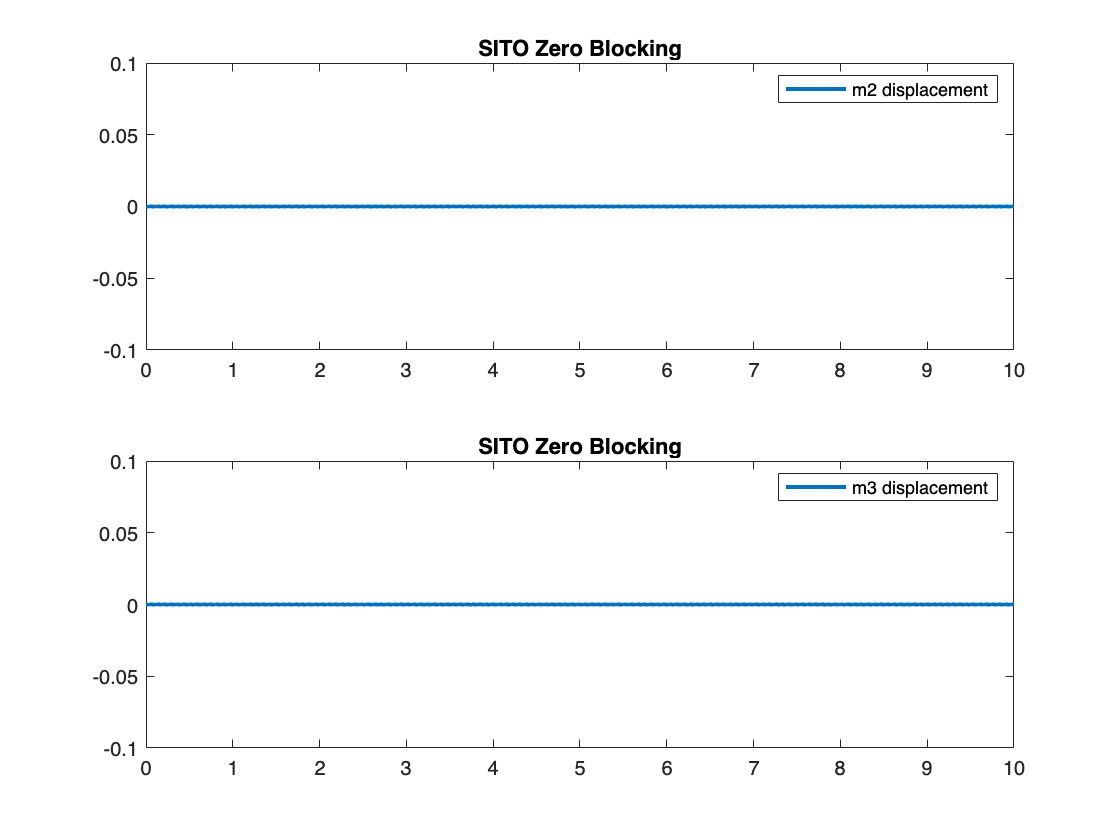

% Zero State vector
x01_sito = i1_sito(1 : length(A));

% Zero Input vector
u01_sito = i1_sito(length(A)+1 : end);

% Zero blocking input 
u1_sito = u01_sito*exp(z1_sito*t);

% Simulation 
[y_sito,t_sito] = lsim(MSD_SITO,u1_sito,t,x01_sito);

figure()
subplot(2,1,1)
plot(t_sito,y_sito(:,1),'LineWidth',2)
ylim([-0.1,0.1])
title("SITO Zero Blocking")
legend('m2 displacement')
subplot(2,1,2)
plot(t_sito,y_sito(:,2),'LineWidth',2)
ylim([-0.1,0.1])
title("SITO Zero Blocking")
legend('m3 displacement')

# Problem 2: Decoupling

Let's condider once again the original HW03 3-SMD TITO system.

B = [zeros(3,2); 1/m1 0; 0 0; 0 1/m3];
C = [[1 0 0; 0 0 1], zeros(2,3)];
D  = zeros(2,2);

MSD = ss(A,B,C,D); MSD.u = {'f1','f3'}; MSD.y = {'z1','z3'};

% TITO Transfer Function Matrix 
G = zpk(MSD);
tzero(MSD)

ans =   -6.7333 + 5.2911i
  -6.7333 - 5.2911i


Since there's no minimum phase zeros (or poles), we don't have to withstand all the limitations arising with their presence and proceed with the Decoupling analysis.

## Simple Decoupling

Considering  $G\left(s\right)=\left\lbrack \begin{array}{cc}
g_{11} \left(s\right) & g_{12} \left(s\right)\\
g_{21} \left(s\right) & g_{22} \left(s\right)
\end{array}\right\rbrack$, we want to make $\bar{G} =G\;D_s$ diagonal. To do so, we define the simplified decoupling $D_s \left(s\right)$ as :

$D_s \left(s\right)=\left\lbrack \begin{array}{cc}
1 & d_{12} \left(s\right)\\
d_{21} \left(s\right) & 1
\end{array}\right\rbrack$ with: $d_{12} \left(s\right)=-\frac{g_{12} \left(s\right)}{g_{11} \left(s\right)}$ ; $d_{21} \left(s\right)=-\frac{g_{21} \left(s\right)}{g_{22} \left(s\right)}$

With this choice, the decoupled system becomes:


$$\bar{G} \left(s\right)=G\left(s\right)D_s \left(s\right)=\left\lbrack \begin{array}{cc}
g_{11} \left(s\right)-\frac{g_{21} \left(s\right)g_{12} \left(s\right)}{g_{22} \left(s\right)} & 0\\
0 & g_{22} \left(s\right)-\frac{g_{12} \left(s\right)g_{21} \left(s\right)}{g_{11} \left(s\right)}
\end{array}\right\rbrack$$


% Extract g_ij elements
g11 = MSD(1,1); g12 = MSD(1,2); g21 = MSD(2,1); g22 = MSD(2,2);

% Off-diagonal Compensator element d_ij
d12 = -(minreal(g12/g11));

9 states removed.


d21 = -(minreal(g21/g22));

9 states removed.


% Simplified decoupling compenastor
Ds = [1 d12; d21 1];

% Apparent Plant
G_bar = G*Ds;

% Simplify apparent plant
G_bar = [zpk(minreal(G_bar(1,1))) zpk(minreal(G_bar(1,2)));
         zpk(minreal(G_bar(2,1))) zpk(minreal(G_bar(2,2)))]

16 states removed.
20 states removed.


20 states removed.
16 states removed.

G_bar =
 
  From input "z3" to output...
                  (s^2 + 13.47s + 73.33)
   z1:  ------------------------------------------
        (s^2 + 14.14s + 60.78) (s^2 + 4.424s + 17)
 
   z3:  0
 
  From input "z1" to output...
   z1:  0
 
                 2 (s^2 + 13.47s + 73.33)
   z3:  ------------------------------------------
        (s+32.92) (s+8.109) (s^2 + 2.633s + 4.994)
 
Continuous-time zero/pole/gain model.


% Decentralized controllers - PI: Kp + Ki/s
C_PID1 = 20 + 30/s; C_PID1.u = 'ey(1)'; C_PID1.y = 'f(1)';
C_PID2 = 8 + 14/s; C_PID2.u = 'ey(2)'; C_PID2.y = 'f(2)';

## Simulation

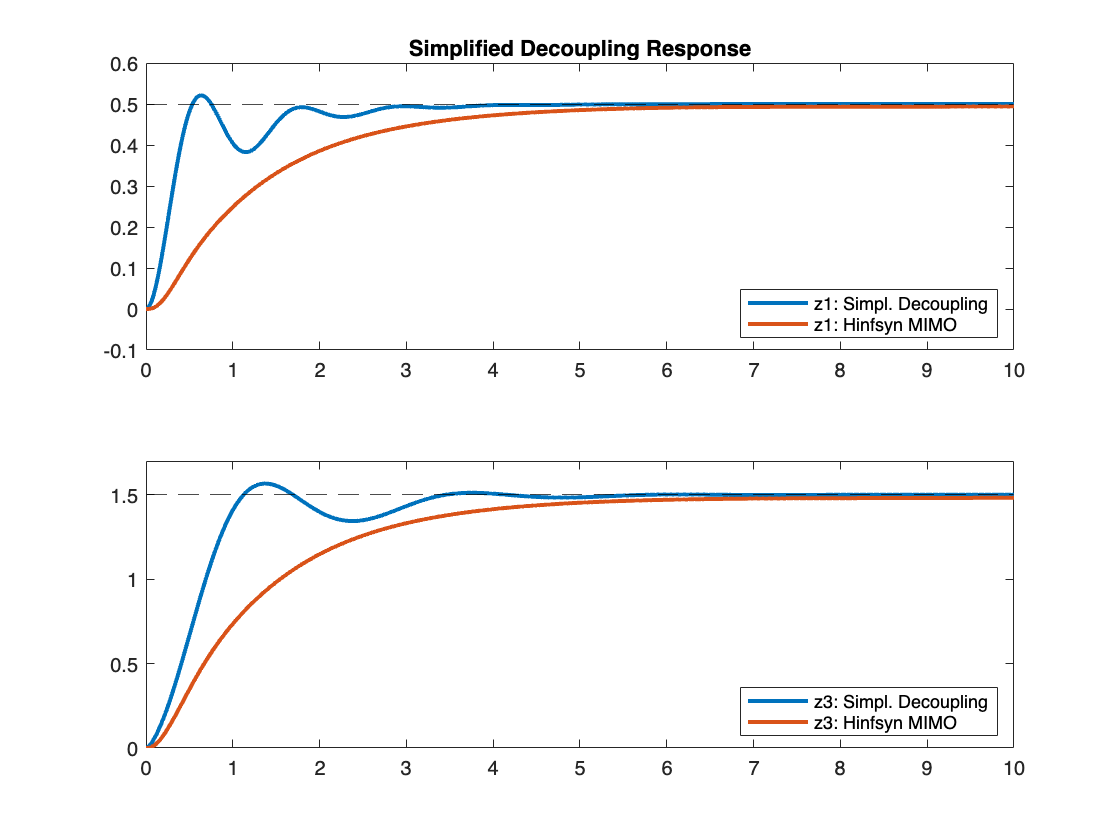

r = [0.5; 1.5];
t = 0:0.01:10;

% Baseline controller to be Hinf controller designed in HW03  
CL_base = loopsens(G,C_hinfsyn).To;

% Simulate System with hinf centralized controller
[y_base, t_base] = lsim(CL_base,r.*ones(2,length(t)),t);

% Build Simple decoupling simulation scheme
G_bar.u = {'f'}; G_bar.y = {'z'};
Sum1 = sumblk('ey(1) = r(1) - z(1)',1);
Sum2 = sumblk('ey(2) = r(2) - z(2)',1);

% Close loops with decentralized controllers
CL_simple = minreal(connect(G_bar,C_PID1,C_PID2, Sum1,Sum2, {'r'},{'z'}));

% Simulate system with Simple decoupling decentralized controllers
[y_simple, t_simple] = lsim(CL_simple,r.*ones(2,length(t)),t);

figure()
subplot(2,1,1)
plot(t_simple,y_simple(:,1),t_base,y_base(:,1),'LineWidth',2)
yline(r(1),'k--')
title("Simplified Decoupling Response")
legend('z1: Simpl. Decoupling','z1: Hinfsyn MIMO','Location','southeast')
subplot(2,1,2)
plot(t_simple,y_simple(:,2),t_base,y_base(:,2),'LineWidth',2)
yline(r(2),'k--')
ylim([0,1.7])
legend('z3: Simpl. Decoupling','z3: Hinfsyn MIMO','Location','southeast')

## Inverted Decoupling

% Desired Loop Function
xi = 2;
omeg = 20;
W = 1/(s^2/omeg^2 + 2*xi/omeg*s + 1);

% L_des = [Li_des 0; 0 Li_des];
L1 = minreal(W/(1-W))

L1 =
 
     400
  ----------
  s^2 + 80 s
 
Continuous-time transfer function.
Model Properties


% Decoulping blocks
dd11 = minreal(L1/(MSD(1,1)));

3 states removed.


dd22 = minreal(L1/MSD(2,2));

3 states removed.


do12 = - minreal(MSD(1,2)/L1);

3 states removed.


do21 = - minreal(MSD(2,1)/L1);

3 states removed.


### Preliminary Compensator

% D = Dd(I - DoDd)^-1
Dd = [dd11 0; 0 dd22];
Do = [0 do12; do21 0];

% Use personalized function to perform all zero-pole cancellations
% and visualize compensator
D = zpk(manual_simplify(Dd*inv(eye(2) - Do*Dd)))

D =
 
  From input "z1" to output...
       400 (s^2 + 14.14s + 60.78) (s^2 + 4.424s + 17)
   1:  ----------------------------------------------
              s (s+80) (s^2 + 13.47s + 73.33)
 
           -20000 (s+6.667) (s+2)
   2:  -------------------------------
       s (s+80) (s^2 + 13.47s + 73.33)
 
  From input "z3" to output...
           -20000 (s+6.667) (s+2)
   1:  -------------------------------
       s (s+80) (s^2 + 13.47s + 73.33)
 
       200 (s+32.92) (s+8.109) (s^2 + 2.633s + 4.994)
   2:  ----------------------------------------------
              s (s+80) (s^2 + 13.47s + 73.33)
 
Continuous-time zero/pole/gain model.


% Inverted Decoupling: simulation scheme
MSD.u = 'u';
MSD.y = 'y';

Sum1 = sumblk('ey(1) = r(1) - y(1)');
Sum2 = sumblk('ey(2) = r(2) - y(2)');

dd11.u = 'u_dd11';
dd11.y = 'u(1)';

do12.u = 'u(2)';
do12.y = 'y_do12';

do21.u = 'u(1)';
do21.y = 'y_do21';

dd22.u = 'u_dd22';
dd22.y = 'u(2)';

Sum3 = sumblk('u_dd11 = y_do12 + ey(1)');
Sum4 = sumblk('u_dd22 = y_do21 + ey(2)');


% Open Loop function coming from compensator + plant ( L(s) = G(s)D(s) )
L_bar = zpk(minreal(connect(MSD, dd11, do12, do21, dd22, Sum3, Sum4,{'ey'},{'y'})));

26 states removed.


% Simplify Loop function
L_bar = zpk([minreal(L_bar(1,1)) 0; 0 minreal(L_bar(2,2))])

L_bar =
 
  From input "ey(1)" to output...
            400
   y(1):  --------
          s (s+80)
 
   y(2):  0
 
  From input "ey(2)" to output...
   y(1):  0
 
            400
   y(2):  --------
          s (s+80)
 
Continuous-time zero/pole/gain model.
Model Properties


% Closed loop decoupled system
CL_inv = zpk(minreal(connect(L_bar, Sum1, Sum2, {'r'}, {'y'})))

CL_inv =
 
  From input "r(1)" to output...
                  400
   y(1):  -------------------
          (s+5.359) (s+74.64)
 
   y(2):  0
 
  From input "r(2)" to output...
   y(1):  0
 
                  400
   y(2):  -------------------
          (s+5.359) (s+74.64)
 
Continuous-time zero/pole/gain model.
Model

### Simulation

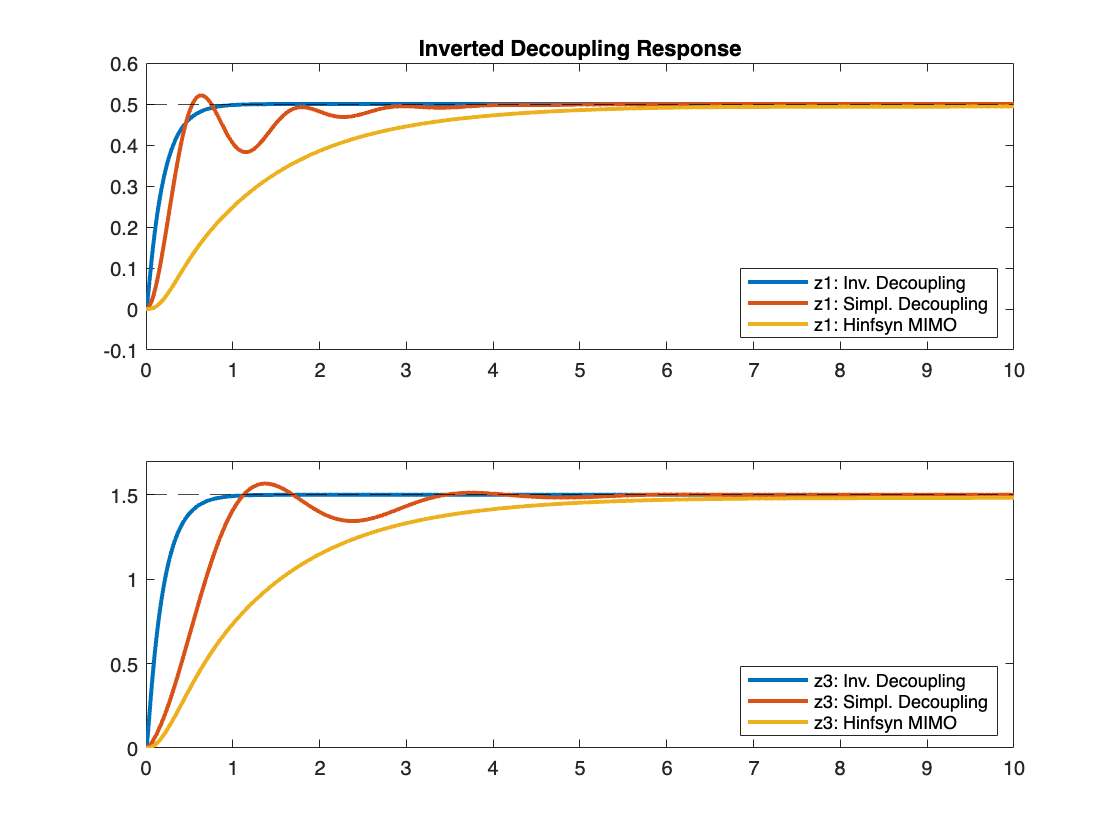

% Simulate system with inverted decoupling
[y_inv, t_inv] = lsim(CL_inv,r.*ones(2,length(t)),t);

figure()
subplot(2,1,1)
plot(t_inv,y_inv(:,1),t_simple,y_simple(:,1),t_base,y_base(:,1),'LineWidth',2)
yline(r(1),'k--')
title("Inverted Decoupling Response")
legend('z1: Inv. Decoupling','z1: Simpl. Decoupling','z1: Hinfsyn MIMO','Location','southeast')
subplot(2,1,2)
plot(t_inv,y_inv(:,2),t_simple,y_simple(:,2),t_base,y_base(:,2),'LineWidth',2)
yline(r(2),'k--')
ylim([0,1.7])
legend('z3: Inv. Decoupling','z3: Simpl. Decoupling','z3: Hinfsyn MIMO','Location','southeast')

## Steady-State Simplified Decoupling

G0 = evalfr(MSD,0);

% Extract g_ij elements
g11_ss = G0(1,1); g12_ss = G0(1,2); g21_ss = G0(2,1); g22_ss = G0(2,2);

% Off-diagonal Compensator element d_ij
d12_ss = - g12_ss/g11_ss;
d21_ss = - g21_ss/g22_ss;

% Simplified decoupling compenastor
D_ss = tf([1 d12_ss; d21_ss 1]);

% Apparent Plant
G_bar_ss = G*D_ss;

% Simplify apparent plant
G_bar_ss = [zpk(minreal(G_bar_ss(1,1))) zpk(minreal(G_bar_ss(1,2)));
         zpk(minreal(G_bar_ss(2,1))) zpk(minreal(G_bar_ss(2,2)))]

G_bar_ss =
 
  From input 1 to output...
                    (s+34.9) (s+7.751) (s^2 + 1.014s + 1.749)
   z1:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
                     -1.2903 s (s+12.5) (s+7.744) (s-1.677)
   z3:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
  From input 2 to output...
                        - s (s+35.9) (s+7.617) (s+0.1512)
   z1:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
                 2 (s^2 + 18.6s + 86.69) (s^2 - 0.03071s + 4.23)
   z3:  -----------------------------------------------------------------
        (s+33.12) (s+7.75) (s^2 + 0.2631s + 1.416) (s^2 + 7.629s + 18.34)
 
Continuous-time zero/pole/gain model.


evalfr(G_bar_ss,0)

ans =     0.0710   -0.0000
   -0.0000    0.1100


### Simulation

% Build Simple decoupling simulation scheme
G_bar_ss.u = {'f'}; G_bar_ss.y = {'z'};
Sum1 = sumblk('ey(1) = r(1) - z(1)',1);
Sum2 = sumblk('ey(2) = r(2) - z(2)',1);

% Close loops with decentralized controllers
CL_simple_ss = minreal(connect(G_bar_ss,C_PID1,C_PID2, Sum1,Sum2, {'r'},{'z'}));

18 states removed.


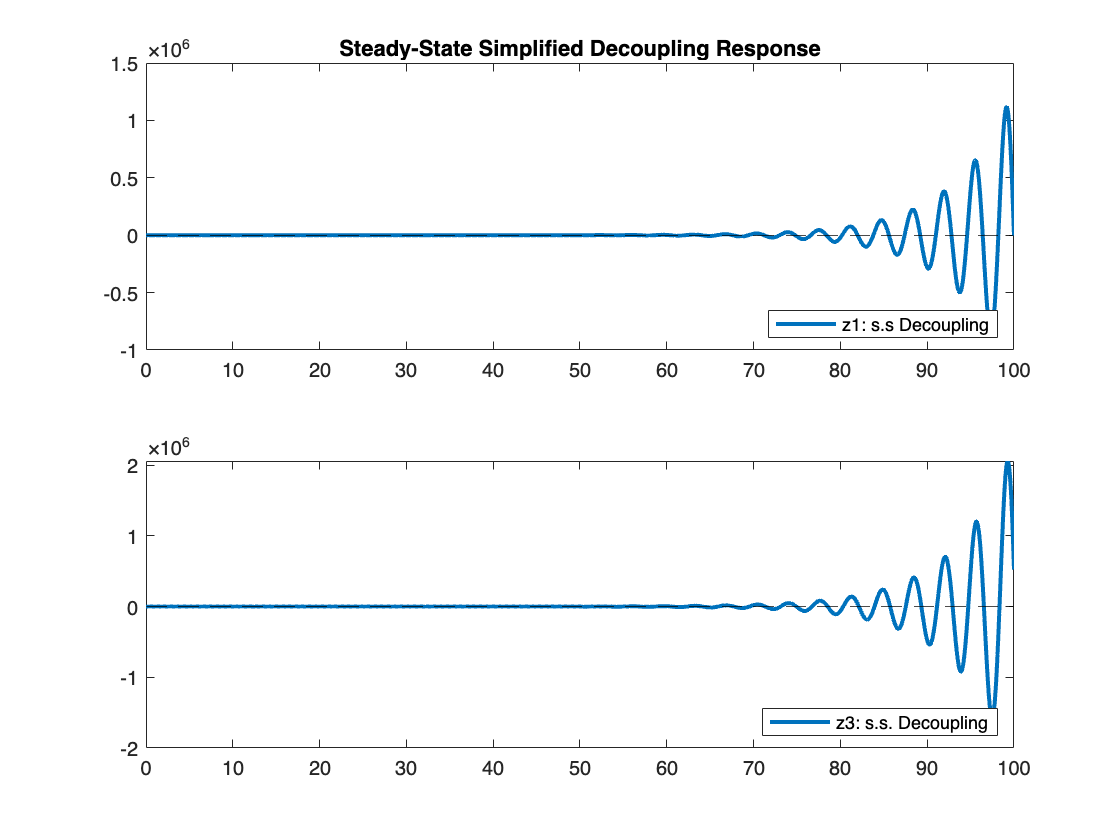

t2 = 0:0.1:100;
% Simulate system with Simple decoupling decentralized controllers
[y_ss, t_ss] = lsim(CL_simple_ss,r.*ones(2,length(t2)),t2);

figure()
subplot(2,1,1)
plot(t_ss,y_ss(:,1),'LineWidth',2)
yline(r(1),'k--')
title("Steady-State Simplified Decoupling Response")
legend('z1: s.s Decoupling','Location','southeast')
subplot(2,1,2)
plot(t_ss,y_ss(:,2),'LineWidth',2)
yline(r(2),'k--')
legend('z3: s.s. Decoupling','Location','southeast')

## Sequential Loop Closure

%Costruzione controllore in base al plant in posizione [2,2]
ops = pidtuneOptions('DesignFocus','reference-tracking');
[C2, ~] = pidtune(g22, 'PID',ops)

C2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 18.6, Ki = 8.14, Kd = 10.6
 
Continuous-time PID controller in parallel form.
Model Properties


%sequential loop closure new system
LC_1 = g11 - g12*C2*g21/(1 + C2*g22);

%Last controller
[C1,~] = pidtune(LC_1, 'PID',ops);

%%%%    SEQUELTIAL LOOP CLOSURE AUG. SYS    %%%%

C1.u = 'ey(1)';
C1.y = 'u(1)';

C2.u = 'ey(2)';
C2.y = 'u(2)';

Sum1 = sumblk('ey(1) = r(1) - y(1)');
Sum2 = sumblk('ey(2) = r(2) - y(2)');



CL_slc = minreal(connect(MSD, C1, C2, Sum1, Sum2, {'r'}, {'y'}));

4 states removed.


### Simulation

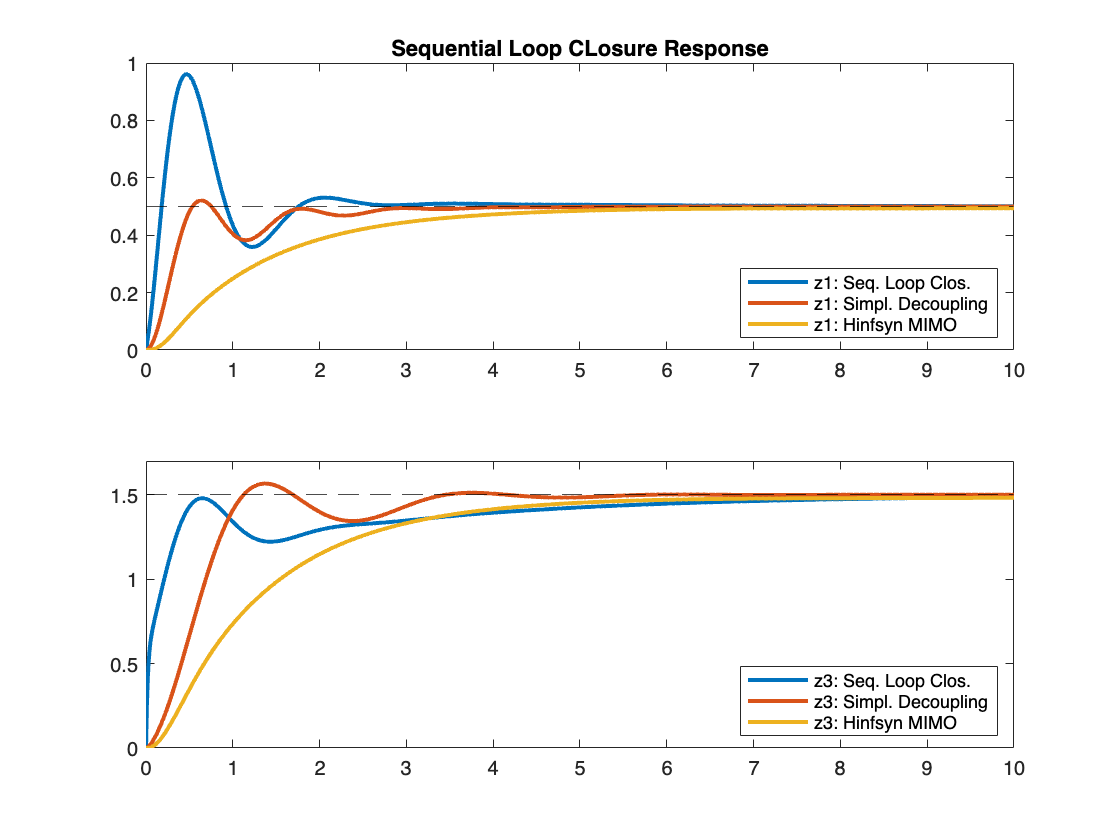

% Simulate system with sequential loop closure
[y_slc, t_slc] = lsim(CL_slc,r.*ones(2,length(t)),t);

figure
subplot(2,1,1)
plot(t_slc,y_slc(:,1),t_simple,y_simple(:,1),t_base,y_base(:,1),'LineWidth',2)
yline(r(1),'k--')
title("Sequential Loop CLosure Response")
legend('z1: Seq. Loop Clos.','z1: Simpl. Decoupling','z1: Hinfsyn MIMO','Location','southeast')
subplot(2,1,2)
plot(t_slc,y_slc(:,2),t_simple,y_simple(:,2),t_base,y_base(:,2),'LineWidth',2)
yline(r(2),'k--')
ylim([0,1.7])
legend('z3: Seq. Loop Clos.','z3: Simpl. Decoupling','z3: Hinfsyn MIMO','Location','southeast')

# Problem 4: Limitations

### Non Minimum Phase Zero

G_nmp = [(s-2)/((s+10)*(s+2)) (s+1)/((s+10)*(s+2)); 
    (s+1)/((s+10)*(s+2)) (s-2)/((s+10)*(s+2))]

G_nmp =
 
  From input 1 to output...
            s - 2
   1:  ---------------
       s^2 + 12 s + 20
 
            s + 1
   2:  ---------------
       s^2 + 12 s + 20
 
  From input 2 to output...
            s + 1
   1:  ---------------
       s^2 + 12 s + 20
 
            s - 2
   2:  ---------------
       s^2 + 12 s + 20
 
Continuous-time transfer function.
Model Properties


G_nmp_ss = minreal(ss(G_nmp));
% Dynamics' Matrices 
A_nmp = G_nmp_ss.A; 
B_nmp = G_nmp_ss.B; 
C_nmp = G_nmp_ss.C; 
D_nmp = G_nmp_ss.D; 

I = eye(size(A_nmp));
S = [x*I-A_nmp -B_nmp; C_nmp D_nmp];

z_nmp = tzero(G_nmp_ss)

z_nmp = 0.5000

% Obtain the transmissions zeros as det|S| = 0
double(solve(det(S) == 0,x))

ans = 0.5000

### Limitations 

% Extract g_ij elements
g11_nmp = G_nmp(1,1); g12_nmp = G_nmp(1,2); g21_nmp = G_nmp(2,1); g22_nmp = G_nmp(2,2);

% Diagonal Compensator element d_ii
d11_nmp = - g22_nmp/g21_nmp;
d22_nmp = - g11_nmp/g12_nmp;

% Off-Diagonal Compensator element d_ij
d12_nmp = - g12_nmp/g11_nmp;
d21_nmp = - g21_nmp/g22_nmp;

% Simplified decoupling compenastor (unstable)
D2_nmp = zpk(minreal([1 d12_nmp; d21_nmp 1]))

D2_nmp =
 
  From input 1 to output...
   1:  1
 
       - (s+1)
   2:  -------
        (s-2)
 
  From input 2 to output...
       - (s+1)
   1:  -------
        (s-2)
 
   2:  1
 
Continuous-time zero/pole/gain model.
Model Properties


% First of all we have to use a different compensator since chosing the non
% symmetric one we'd get g12/g11 which is unstable

% Usable compensator
D1_nmp = manual_simplify([d11_nmp 1; 1 d22_nmp])

D1_nmp =
 
  From input 1 to output...
       -s + 2
   1:  ------
       s + 1
 
   2:  1
 
  From input 2 to output...
   1:  1
 
       -s + 2
   2:  ------
       s + 1
 
Continuous-time transfer function.
Model Properties


% Apparent Plant
G_bar_nmp = G_nmp*D1_nmp;

% Simplify apparent plant
G_bar_nmp = [zpk(minreal(G_bar_nmp(1,1))) zpk(minreal(G_bar_nmp(1,2)));
    zpk(minreal(G_bar_nmp(2,1))) zpk(minreal(G_bar_nmp(2,2)))]

G_bar_nmp =
 
  From input 1 to output...
       6 (s+10) (s+2) (s-0.5)
   1:  ----------------------
       (s+10)^2 (s+2)^2 (s+1)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       6 (s+10) (s+2) (s-0.5)
   2:  ----------------------
       (s+10)^2 (s+2)^2 (s+1)
 
Continuous-time zero/pole/gain model.
Mo

% Better use "personalized" semplification tool
G_bar_nmp = manual_simplify(G_bar_nmp)

G_bar_nmp =
 
  From input 1 to output...
           6 (s-0.5)
   1:  ------------------
       (s+10) (s+2) (s+1)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
           6 (s-0.5)
   2:  ------------------
       (s+10) (s+2) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


### Controller Design

For the NMP I/O channels, we have $z=0\ldotp 5$  and we  have:


$$ \|{S(s)  w_S(s)\} \|_{\infty} < 1 
\\with:
\\\|{S(s)  w_S(s)\} \|_{\infty} \geq |w_S(z)|
$$


and therefore we need to impose:

$|w_S(z)| < 1$.

% Sensitivity Weight "balanced"
Ms1 = 1.01;
B3s1 = 0.3;
As1 = 0.01;

% Sensitivity Weight "greedy"
Ms2 = 1.01;
B3s2 = 1;
As2 = 0.01;

Ws1 = (s/Ms1+B3s1)/(s+B3s1*As1);
Ws2 = (s/Ms2+B3s2)/(s+B3s2*As2);
[C_w1,~,gam1] = mixsyn(G_bar_nmp(1,1),Ws1,1/100,[]);
[C_w2,~,gam2] = mixsyn(G_bar_nmp(1,1),Ws2,1/100,[]);


% Make a copy of the "balanced" controller
C_w11 = C_w1;
C_w1.u = 'ey(1)'; C_w1.y = 'f(1)'; 
C_w11.u = 'ey(2)'; C_w11.y = 'f(2)'; 

% Make a copy of the "greedy" controller
C_w22 = C_w2;
C_w2.u = 'ey(1)'; C_w2.y = 'f(1)'; 
C_w22.u = 'ey(2)'; C_w22.y = 'f(2)'; 


% Build Simple decoupling simulation scheme
G_bar_nmp.u = {'f'}; G_bar_nmp.y = {'z'};
Sum1 = sumblk('ey(1) = r(1) - z(1)',1);
Sum2 = sumblk('ey(2) = r(2) - z(2)',1);

% Close loops with "balanced" decentralized controllers
CL_w1 = minreal(connect(G_bar_nmp,C_w1,C_w11, Sum1,Sum2, {'r'},{'z'}));

6 states removed.


% Close loops with "greedy" decentralized controllers
CL_w2 = minreal(connect(G_bar_nmp,C_w2,C_w22, Sum1,Sum2, {'r'},{'z'}));

2 states removed.


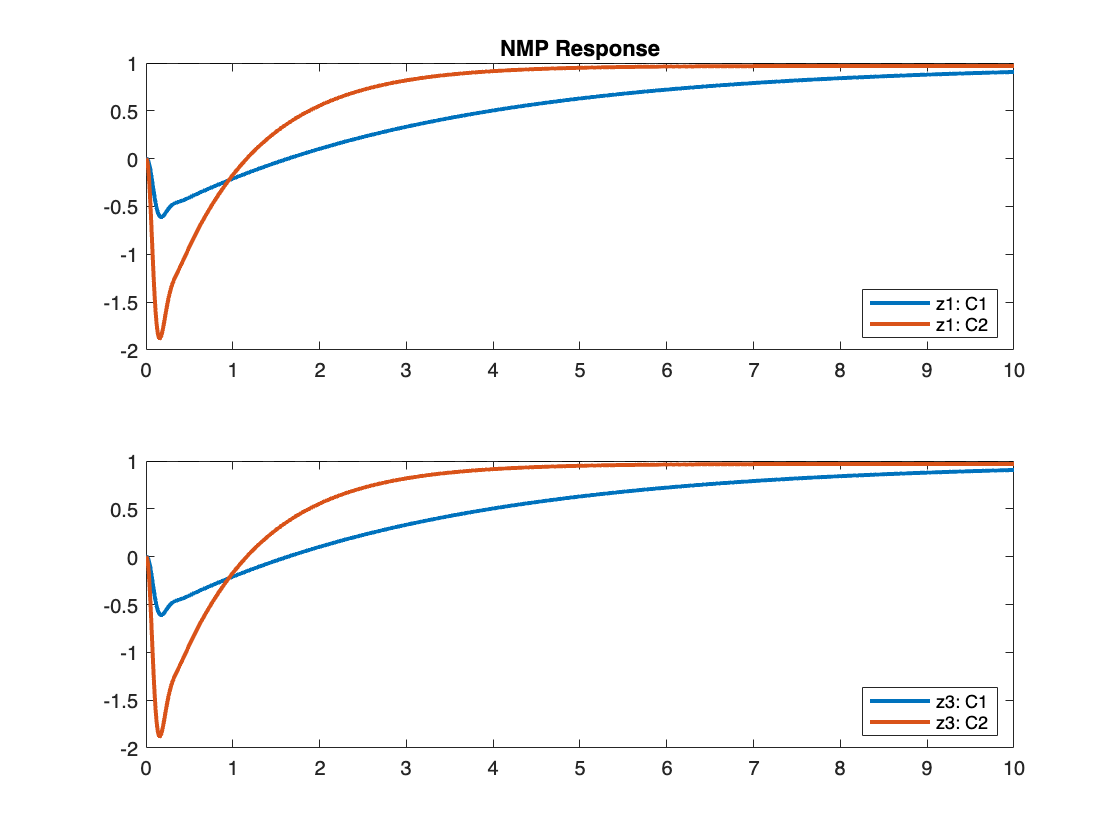

% Simulate the two closed loop systems
[y_w1, t_w1] = lsim(CL_w1,ones(2,length(t)),t);
[y_w2, t_w2] = lsim(CL_w2,ones(2,length(t)),t);


figure()
subplot(2,1,1)
plot(t_w1,y_w1(:,1),t_w2,y_w2(:,1),'LineWidth',2)
yline(1,'k--')
title("NMP Response")
legend('z1: C1','z1: C2','Location','southeast')
subplot(2,1,2)
plot(t_w1,y_w1(:,2),t_w2,y_w2(:,2),'LineWidth',2)
yline(1,'k--')
legend('z3: C1','z3: C2','Location','southeast')

### Remark: Sensitivity peaks

Notice how bandwidth limitation affects sensitivity peak

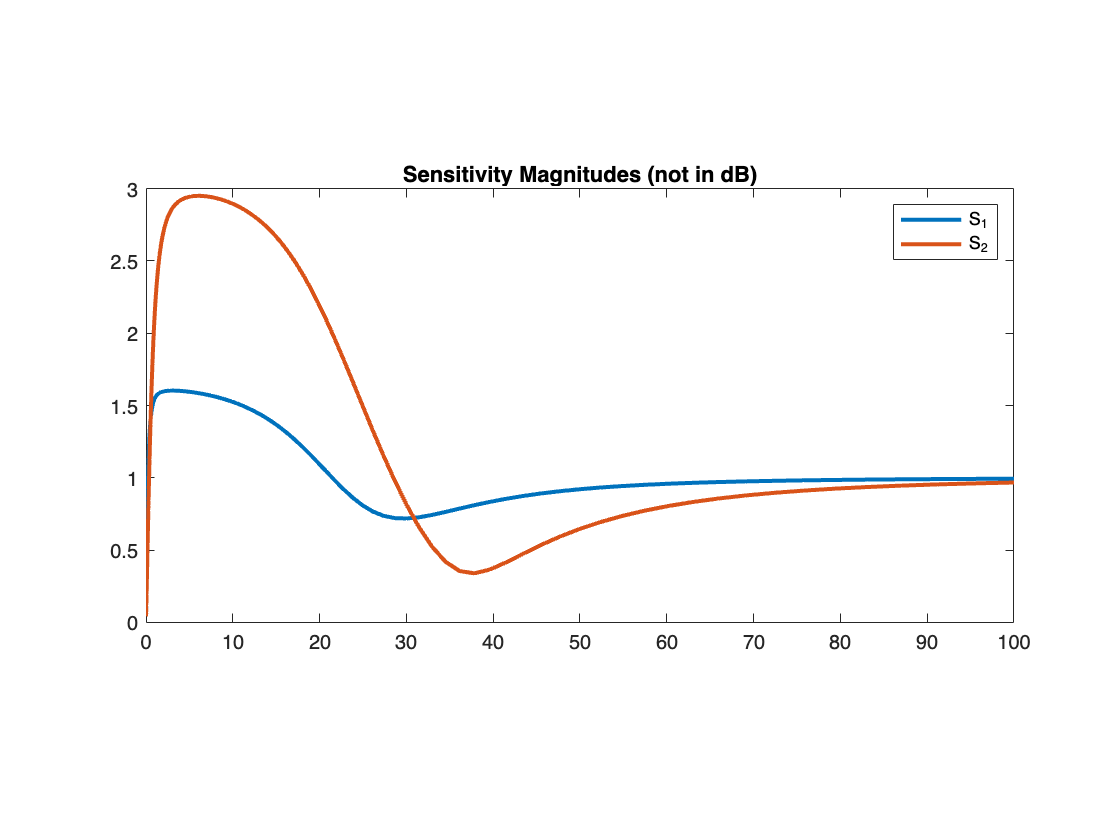

ls1 = loopsens(G_bar_nmp(1,1), C_w1);
ls2 = loopsens(G_bar_nmp(1,1), C_w2);

wc = logspace(-2,2,200);

[mag1,~] = bode(ls1.So, wc);
[mag2,~] = bode(ls2.So, wc);

figure()
plot(wc,mag1(:),wc,mag2(:), 'LineWidth',2)
title("Sensitivity Magnitudes (not in dB)")
legend('S_1','S_2')
pbaspect([2 1 1])

### Direct MIMO Design

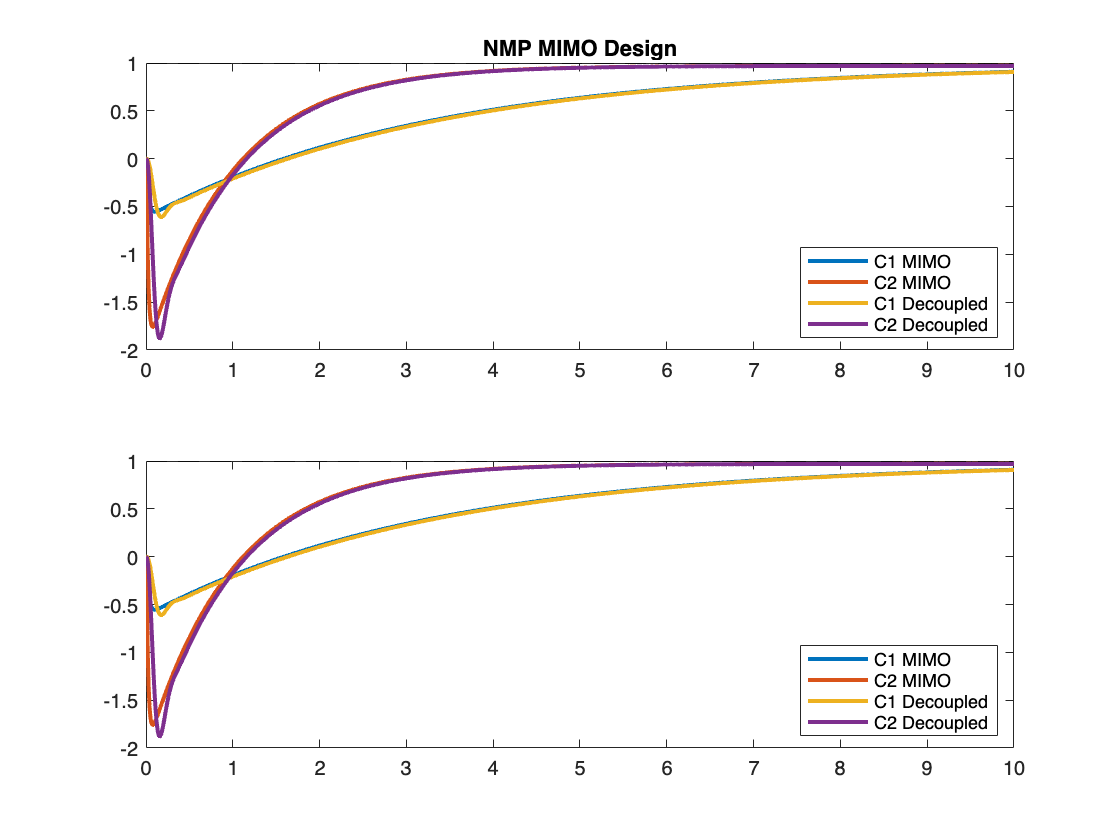

C_m1 = mixsyn(G_nmp,Ws1*eye(2),1/100*eye(2),[]);
C_m2 = mixsyn(G_nmp,Ws2*eye(2),1/100*eye(2),[]);

CL_m1 = loopsens(G_nmp,C_m1).To;
CL_m2 = loopsens(G_nmp,C_m2).To;

% Simulate the two closed loop systems
[y_m1, t_m1] = lsim(CL_m1,ones(2,length(t)),t);
[y_m2, t_m2] = lsim(CL_m2,ones(2,length(t)),t);


figure()
subplot(2,1,1)
plot(t_m1,y_m1(:,1),t_m2,y_m2(:,1),t_w1,y_w1(:,1),t_w2,y_w2(:,1),'LineWidth',2)
yline(1,'k--')
title("NMP MIMO Design")
legend('C1 MIMO','C2 MIMO','C1 Decoupled','C2 Decoupled','Location','southeast')
subplot(2,1,2)
plot(t_m1,y_m1(:,2),t_m2,y_m2(:,2),t_w1,y_w1(:,1),t_w2,y_w2(:,1),'LineWidth',2)
yline(1,'k--')
legend('C1 MIMO','C2 MIMO','C1 Decoupled','C2 Decoupled','Location','southeast')